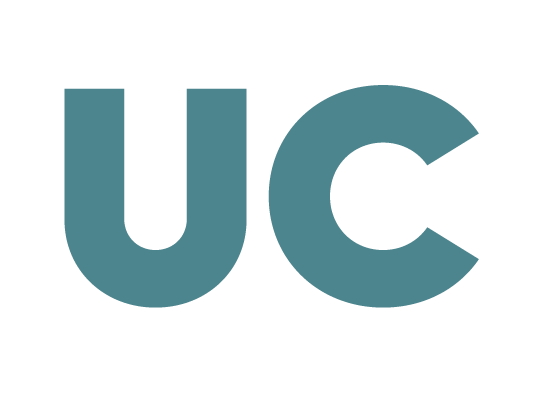

***Grado de Tecnologías de Telecomunicación***

**G282: Álgebra y Geometría**

# **Práctica 11: Aplicaciones lineales (II)**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

**Objetivos**

- Obtención de la matriz de una aplicación lineal (bases diferentes de la canónica)

### **Matriz asociada a una aplicación **

Sea $f$ la siguiente aplicación lineal:


$$\mathit{f}: \mathbb{R}^3 \longrightarrow  \mathbb{R}^2 \\
(x,y,z) \leadsto (x'=2x, y'=-3y+z) $$


Siempre podremos reescribirla en la forma $\vec{x'}=A\vec{x}$ del siguiente modo:


$$\left\lbrack \begin{array}{c}
x^{\prime } \\
y^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
2 & 0 & 0\\
0 & -3 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack$$


Siendo $A$ su matriz asociada en bases canónicas (o matriz estándar). Fíjate que al ser una aplicación que va de $\mathbb{R}^3$ en $\mathbb{R}^2$, $A$ es de tamaño $2 \times 3$. Una vez tenemos $A$, es muy fácil calcular el transformado (es decir, la imagen), de cualquier vector del espacio vectorial inicial, $\mathbb{R}^3$. Por ejemplo, la imagen del $(5,-7,-\pi)$ en $\mathbb{R}^2$ será:

A = [2 0 0; 0 -3 1]  % matriz estándar de f
A*[5 -7 -pi]'  % imagen por f del vector (5, -7, -pi)

Se puede comprobar fácilmente que las columnas de $A$ se corresponden con las imágenes obtenidas mediante $f$ de los vectores de la base canónica del espacio inicial

A*[1 0 0]'  % primera columna de A (imagen del primer vector de la BC de R³
A*[0 1 0]'  % segunda columna de A (imagen del segundo vector de la BC de R³)
A*[0 0 1]'  % tercera columna de A (imagen del tercer vector de la BC de R³)

### Matriz de la aplicación en bases cualesquiera 

Imaginemos nos pidieran la matriz asociada a $f$ en otras bases que no fueran las canónicas, por ejemplo $B =\lbrace (1,0,1), (0,-1,-3), (-2,1,0)\rbrace$ en $\mathbb{R}^3$ y $B' = \lbrace (1,1), (2,-1) \rbrace$ en $\mathbb{R}^2$. Para hallar dicha matriz, $M$, necesitaremos la matriz de paso de $B$ a la base canónica de $\mathbb{R}^3$ (llamémosla $P$)  y la matriz de paso de $B'$ a la base canónica de $\mathbb{R}^2$ (llamémosla $Q$). Sabemos que $P=\left\lbrack \begin{array}{ccc}
1 & 0 & -2\\
0 & -1 & 1\\
1 & -3 & 0
\end{array}\right\rbrack$y $Q=\left\lbrack \begin{array}{cc}
1 & 2\\
1 & -1
\end{array}\right\rbrack$. A partir de aquí sería inmediato obtener $M$, pues sabemos que se cumple la relación $M=Q^{-1}AP$.  

P = [1 0 1; 0 -1 -3; -2 1 0]'  % matriz de paso de B a la BC de R³
Q = [1 1; 2 -1]'  %  matriz de paso de B' a la BC de R²
M = inv(Q)*A*P  % matriz de f en la bases B y B'

### Ejercicios propuestos

**Ejercicio 1:**

En $\mathbb{R}^2$, halla la matriz de reflexión respecto de la recta $y=5x$. Pista: Cuando trabajamos en base canónica, la matriz de reflexión respecto el eje X es  $M=\left\lbrack \begin{array}{cc}
1 & 0\\
0 & -1
\end{array}\right\rbrack$. La matriz que representa la reflexión sobre la recta  $y=5x$ sería M en la base  $B = \lbrace (1,5), (5,-1) \rbrace$

**Ejercicio 2:**

Dada una aplicación lineal $\mathit{f}: \mathbb{R}^4 \longrightarrow  \mathbb{R}^4$ tal que su núcleo es el subespacio de ecuaciones $\lbrace x + y + z = 0,  t = 0 \rbrace$ y los vectores $\lbrace (1,1,1,0), (0,0,0,1) \rbrace$ se transforman por $f$ en sí mismos. Se pide:

- La matriz de  $f$ respecto de la base canónica de $\mathbb{R}^4$ en espacio inicial y final

- La matriz de $f$ en la base $B=\lbrace(-1,0,0,0),(1,0,-2,3),(1,-1,0,2),(-1,-1,-1,0)\rbrace$de $\mathbb{R}^4
$